# Aula 4 - Laboratório de Controle - 2021/1

## Avaliação gráfica do efeito de parâmetros na resposta ao degrau

## Nome: Arthur Lorencini Bergamaschi

I = 1;
Turma = 2;
g2=init(I,Turma)

g2 =
 
         25.6
  ------------------
  s^2 + 9.6 s + 12.8
 
Continuous-time transfer function.



b0=g2.Numerator{1}(3);p0=g2.Denominator{1}(3);

## Atividade 1 - Análise do erro em regime

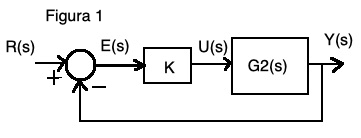

Abaixo são usados 20 valores de ganho $K$ para fechar a malha e calcular o [erro em regime ](http://www.fem.unicamp.br/~em621/aulas/aula16/analiserro.pdf)$E(s)=\frac{R(s)}{1+KG_{2}(s)}$ para uma entrada degrau unitário $R(s)$, conforme a Figura 1. 

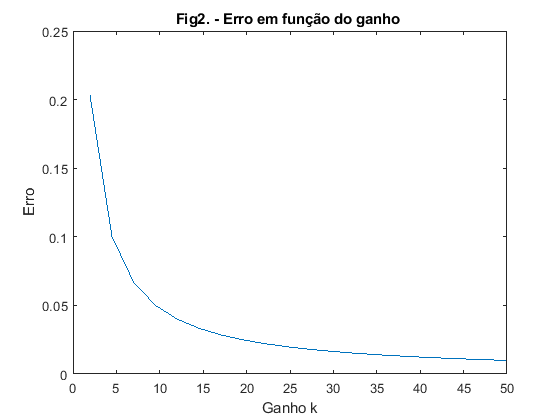

k=linspace(p0/(0.25*b0)-1/b0,p0/(0.01*b0)-1/b0,20);
for i=1:length(k)
    m=feedback(1,k(i)*g2);
    erro(i)=freqresp(m,0);
end
plot(k,erro);title('Fig2. - Erro em função do ganho ');xlabel('Ganho k');ylabel('Erro');

1.1 Qual o efeito do ganho no erro em regime? 

Vemos que ao aumentar o ganho k faz com que o erro caia de forma hiperbólica e se mantém quase constante quando K tende ao infinito depois de um certo ponto.

1.2 Para que valores de ganho K o erro é menor que 5%? 

A partir de 9.5 já faz o K ser menor do que 5%

1.3 Qual o erro em regime para sistemas com **tipo** igual ao de g2?

Sabemos que o tipo de g2 é 0, pois ele não possui nenhum polo na origem. Portanto, o erro aparece para a entrada do degrau unitário apenas, e tem a forma 1/(1+K). Então, conforme o ganho vai aumentando, o erro vai diminuindo para o sistemas de tipo 0 com a entrada do degrau unitário.

Na figura 3 é mostrada a resposta Y(s) ao degrau unitário R(s) bem como o erro E(s) e a integral absoluta do erro (IAE), calculada por $iae=\int_{0}^{3}|e(t)|dt$. Observe que o iae é integrado para cada tempo t. O valor utilizado para comparações é aquele obtido na janela de tempo total, ou seja, em t=3, neste caso igual a 1.25.

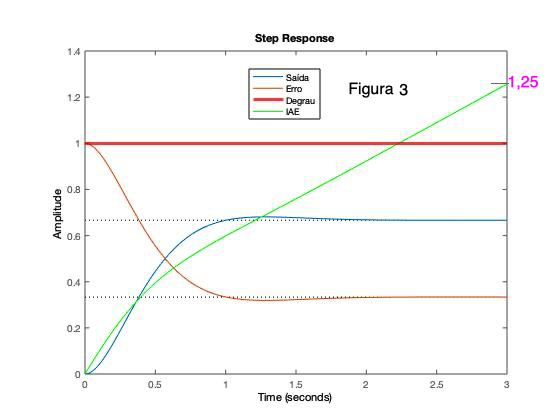

1.4 Observando as figuras 2 e 3, explique o que leva um sistema a ter maiores valores de iae.

O valor de iae aumenta se o tempo de subida for muito grande, isso é causado por um K pequeno, e implica em um erro de regime maior. Com um erro em regime maior, para um mesmo intervalo de tempo, o iae é maior para um K menor do que um K maior.

## Atividade 2 - Erro em regime e resposta transitória

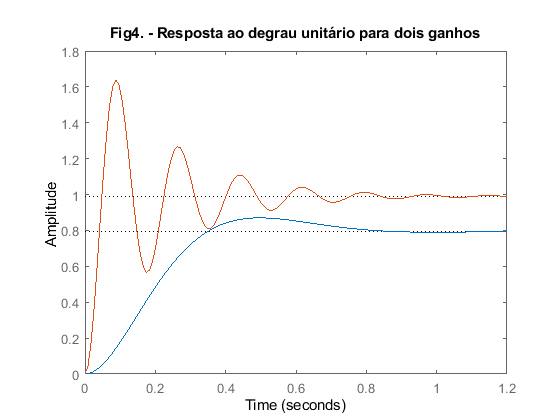

m1=feedback(k(1)*g2,1);
m2=feedback(k(end)*g2,1);
step(m1,m2);
title('Fig4. - Resposta ao degrau unitário para dois ganhos');

2.1 Na figura 4 é mostrada a resposta ao degrau unitário para o menor e maior ganhos usados na figura 2. Compare o efeito do ganho K na resposta ao degrau unitário em regime e no período transitório, informando os ganhos usados.

Na curva azul, vemos que o menor valor de K (=1.9609) tem uma constante de tempo maior, não tem overshoot e o seu erro em regime é de 0.2, um tempo de estabelecimento de 0.8s.

Para a curva vermelha, com K = 49.9609, temos uma constante de tempo menor, um overshoot de 60%, um tempo de estabelecimento idêntico, cerca de 0.8s,

A sobreelevação se relaciona com o amortecimento $\zeta$ pela equação $UP=100 e^-({\frac{\zeta \pi}{\sqrt{1-\zeta^2}}})$. O script abaixo calcula os valores de UP para um conjunto de valores de $\zeta$.

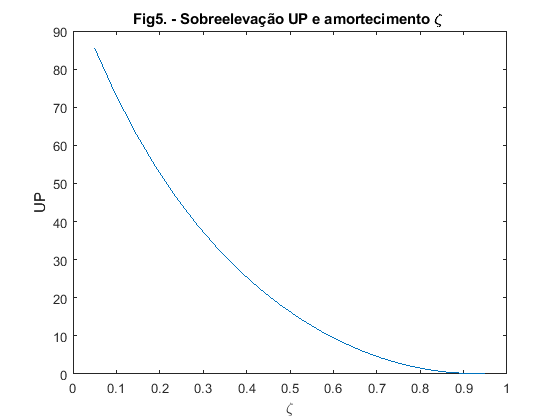

zeta=linspace(0.05,0.95,20);
for i=1:20
UP(i)=100*exp(-zeta(i)*pi/(sqrt(1-zeta(i)^2)));
end
plot(zeta,UP);title('Fig5. - Sobreelevação UP e amortecimento \zeta ');xlabel('\zeta');ylabel('UP')

2.2 Explique a relação entre UP e $\zeta$ usando a figura 5 gerada pelo script.

Vemos que conforme o amortecimento vai aumentando, ele faz diminuir exponencialmente o valor da sobreelevação. Portanto, se o sistema tiver um alto nível de amortecimento, é bem provável que a sua sobreelevação seja pequena.

2.3 Use a figura 5 para obter os valores de $\zeta$para os quais se tem $UP\leq 5\%$?

O valor do amortecimento é de 0.71.

## Atividade 3 - Análise da resposta transitória

Use o comando rlocus(g2) ou rlocus(g2,k) para obter k1 de modo a ter $\zeta=0.9$ e k2 de modo a ter $\zeta=0.1$, e substitua estes valores abaixo e execute o script. 

## Importante: mostre a figura gerada pelo script abaixo ao professor antes de responder as 4 perguntas desta atividade.

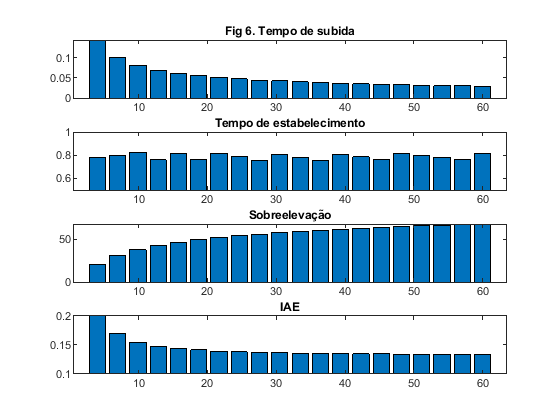

k=linspace(4,60,20);
for i=1:20
    m=feedback(k(i)*g2,1);
    s=stepinfo(m);
    U(i,:)=[s.RiseTime s.SettlingTime s.Overshoot];
    if i==1 
        [y,t]=step(m);Tempo=max(t);
    else
        [y,t]=step(m,Tempo);
    end
    IAE(i)=trapz(t,abs(1-y));
end

subplot(4,1,1);bar(k,(U(:,1)));title('Fig 6. Tempo de subida');
subplot(4,1,2);bar(k,(U(:,2)));title('Tempo de estabelecimento');
ylim([0.5 1])
subplot(4,1,3);bar(k,(U(:,3)));title('Sobreelevação');
subplot(4,1,4);bar(k,(IAE));title('IAE');
ylim([0.1 0.2])

3.1 Qual o efeito do ganho K no tempo de subida ($t_r$)?

Inicialmente, com K = 4, vemos que o tempo de subida é de 0.14s. Com K = 13, temos que o tempo de subida cai para a metade, 0.07s, e para K= 60, finalmente temos um tempo de subida de 0.03s

3.2 Qual o efeito do ganho K na sobreelevação (UP)?

Com K = 4, temos um valor de sobreelevação de 20% e conforme o K vai aumentando, por exemplo, com K = 40, temos uma sobreelevação de 60%, e finalmente, com K = 60, temos a sobreelevação de 67%.

3.3 Explique o comportamento do tempo de estabelecimento ($t_s$) quando o ganho K varia.

O tempo de estabelecimento pode ser descrito usando a fórmula:

E a partir daí, podemos ver que o Ganho não tem efeito significativo sobre o tempo de estabelecimento.

3.4 Quem afeta mais o valor de IAE? UP, $t_r$ ou $t_s$?

Vemos que um tempo de subida alto implica em um valor de IAE alto, como mostra a figura 3 e 6. O tempo de estabelecimento não causa nenhum efeito visível, pois a sua variação implica em quase nada no IAE. O UP tem um efeito contrário, conforme as figuras, que quanto maior a sobre elevação, menor o IAE.

datetime('now')

ans = datetime
   07-Jul-2021 13:32:50


pwd

ans = 'C:\Users\malaquias\Desktop\UFES\UFES-LCA\Aula4'